# **Project 1**

BENG280A FQ23 Group#23

Due: 11/8/2023

## Set up a phantom to scan

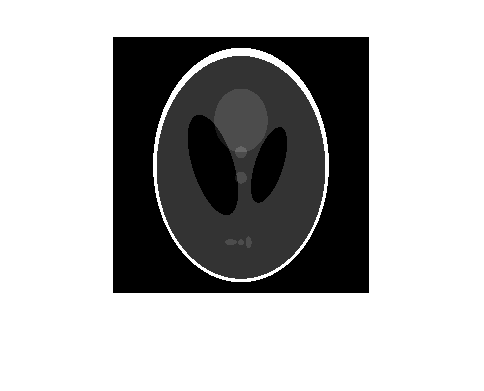

p = phantom(256);
imshow(p)

## Set up scan type

scan_type = "parallel";
if scan_type == "parallel"
    thetas = 0:1:180; % parallel beam only needs 180 degrees
    scan = @(x) radon(x,thetas); % default angle 0:1:180
    iscan = @(x) iradon(x, thetas);
    % unsure if x axis & y-axis are accurate but testing
    showSino = @(x) imshow(x, [], 'Xdata', 0:180, 'Ydata', 0:150, 'InitialMagnification', 'fit')
else
    thetas = 0:1:359 % fan-beam does 360 angles
    scan = @(x) fanbeam(x, 550); % default distance 550 to fit fan-beam
    iscan = @(x) ifanbeam(x, 550);
    showSino = @(x) imshow(x, [], 'Xdata', 0:360, 'Ydata', 0:150, 'InitialMagnification', 'fit');
end

showSino = function_handle with value:
    @(x)imshow(x,[],'Xdata',0:180,'Ydata',0:150,'InitialMagnification','fit')



beam_type = scan_type; % for naming graphs later
beam_type{1}(1) = upper(beam_type{1}(1));

## Scan phantom

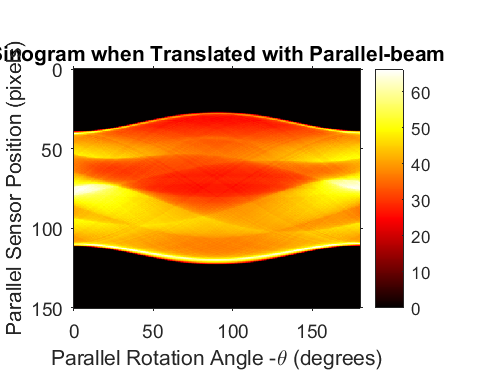

sinogram = scan(p);

showSino(sinogram)
xlabel(beam_type + ' Rotation Angle -\theta (degrees)')
ylabel(beam_type + ' Sensor Position (pixels)')
axis on
colormap(gca, hot), colorbar
title('Sinogram when Translated with ' + beam_type + '-beam')

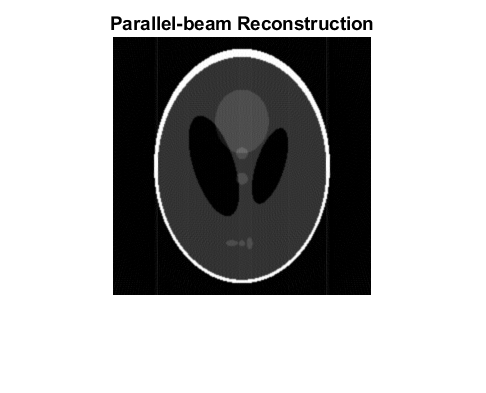


imshow(iscan(sinogram))
title(beam_type + '-beam Reconstruction')

## Simulate movement

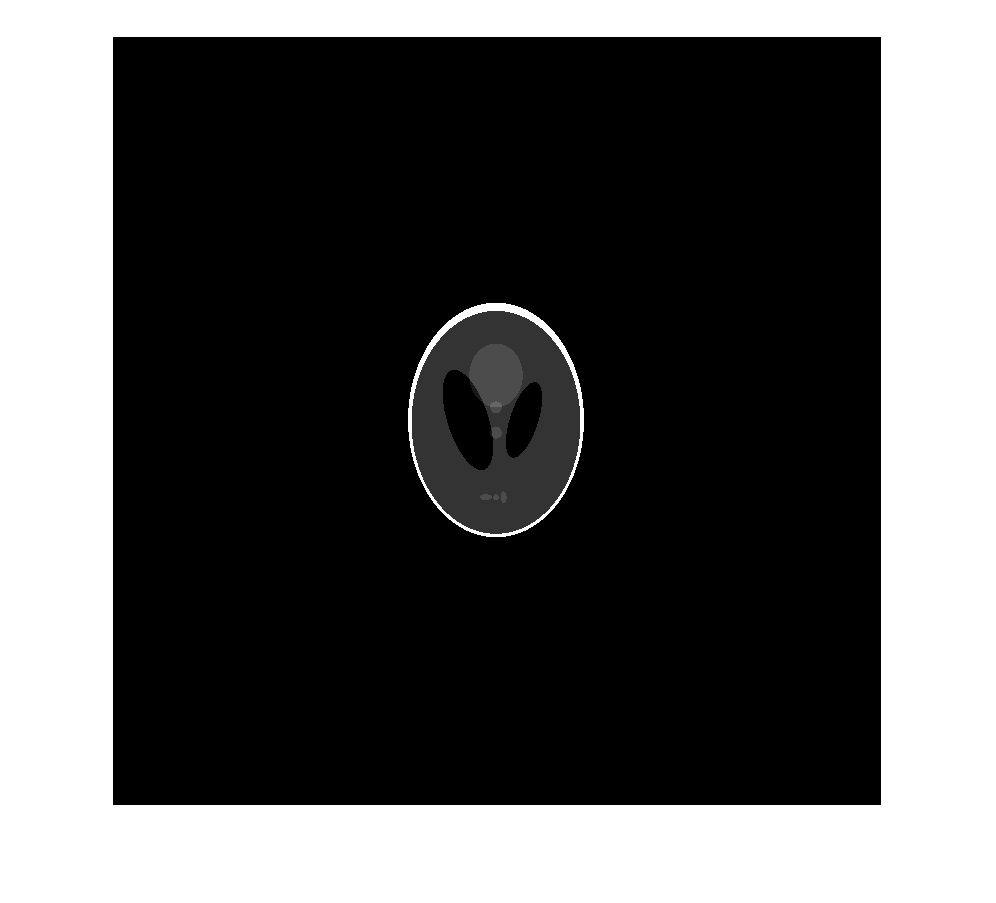

% generate a field in which the subject moves and/or rotate
field = zeros(size(p)*3);
xloc = length(field)/2; % where the subject locates in image
yloc = xloc;

p_temp = p;

imshow(draw(field, p_temp, yloc, xloc))

Error using exportgraphics
File format 'gif' is not valid for export.

initial_scan = zeros(size(scan(draw(field, p_temp, yloc, xloc)))); % create initial sinogram array matrix

filename = "gradual_rotation_translation_-1+1_pb.gif"; % pb = parallel-beam, fb = fan-beam

for theta = thetas
    img_temp = draw(field, p_temp, round(yloc), round(xloc));
    scan_temp = scan(img_temp);
    initial_scan(:, theta+1) = scan_temp(:, theta+1);
    xloc = xloc - 1; % motion along x-axis towards left
    yloc = yloc + 1; % motion along y-axis downward
    p_temp = imrotate(p_temp, -2, "bilinear", "crop"); % rotate the object and crop if necessary

    % making a gif
    imshow(img_temp)
    exportgraphics(gca, filename, "Append", true)

end


showSino(initial_scan)
xlabel(beam_type + ' Rotation Angle -\theta (degrees)')
ylabel(beam_type + ' Sensor Position (pixels)')
axis on
colormap(gca, hot), colorbar
title('Sinogram when Translated with ' + beam_type + '-beam')

imshow(iscan(initial_scan))
title(beam_type + '-beam Reconstruction')

## Expand/Compress (Circle)

% Circle creation method is from "https://matlab.fandom.com/wiki/FAQ#How_do_I_create_a_circle.3F"

#### Variables

imSize = [256 256];     % [px px] 256 x 256 image [x y]
fCT = 20;             % [Hz] frequency CT, angles per second
fExp = 15/60;           % [Hz] rate of expansion/compression (human lungs 12~15 breaths/min)
cenC = [128 128];        % [px px] center of image [x y]
radi = 60;              % [px] starting radius of circle (assuming compressed)
imgOut = 7;             % [px] outline thickness
expand = round(radi*(2^(1/3))) - radi;            % [px] difference in radius btwn smallest/largest circles (human lungs double in volume?)

#### Creating Image

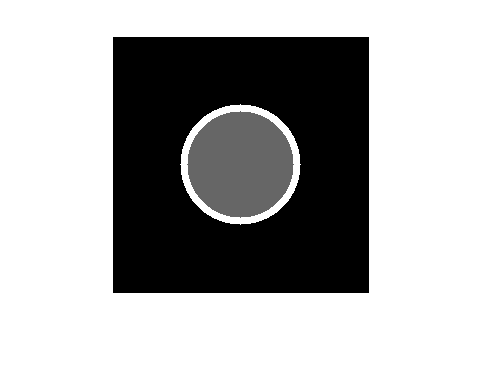

aNum = 360;               % # angles (181)
tCT = aNum/fCT;         % [s] total time of CT scan (# angles * angle freq)
tPxC = 2*expand*fExp;        % [px/s] rate of change in radius
totalPx = 0:(tCT/aNum):tCT;    % total time (tCT) in increments of time corresponding to rate of change in angle

sCompC = zeros(imSize(1), imSize(2), aNum+1);     % array to store all images per angle (including starting image)
[imCol, imRow] = meshgrid(1:imSize(1), 1:imSize(2));    % to use in making circle/ellipse
filename = "ExpCompCircle.gif";       % exp/comp output gif

% Computing and recording image motion for duration of scan
for i=1:length(totalPx)     % increment at sampling times for each angle
    ovR = tPxC*totalPx(i);       % overall change in radius
    modDiv = mod(ovR, expand);  % modulo of overall change in radius by max expansion
    intDiv = (ovR-modDiv)/expand;   % integer division using modulo
    
    % find expansion/compression at time of sampling
    rCurr = radi + expand*(mod(intDiv,2)) + modDiv*(-1)^((ovR-modDiv)/expand);
    
    % Computing projection image at time of sampling
    outC = ((imCol - cenC(1)).^2 + (imRow - cenC(2)).^2) <= rCurr.^2;
    inC = ((imCol - cenC(1)).^2 + (imRow - cenC(2)).^2) <= (rCurr - imgOut).^2;
    sCompC(:, :, i) = outC - inC*(1-0.4);
    
    if i==1
        imwrite((sCompC(:, :, i)*255 +1), filename, "gif", "Loopcount", Inf, "DelayTime", (tCT/aNum));
    else
        imwrite((sCompC(:, :, i)*255 +1), filename, "gif", "WriteMode", "append", "DelayTime", (tCT/aNum));
    end
end
imshow(sCompC(:,:,1))        % image at starting time

#### Scanning

[sinoRC, xpR] = radon(sCompC(:,:,1));     % initializing sinogram at angle 0 deg
vdF = sqrt(imSize(1)^2 + imSize(2)^2) + 1;
[sinoFC, sPF, rAF] = fanbeam(sCompC(:,:,1), vdF);     % initializing sinogram at angle 0 deg

for theta = 2:1:aNum        % increment through angles 1-359 deg
    if (theta <= aNum/2)
       scanRC = radon(sCompC(:,:, theta));
       sinoRC(:, theta) = scanRC(:, theta);  % replacing "slices" of sinogram with image at time corresponding to angle 
    end
    scanFC = fanbeam(sCompC(:,:, theta), vdF);
    sinoFC(:, theta) = scanFC(:, theta);  % replacing "slices" of sinogram with image at time corresponding to angle
end

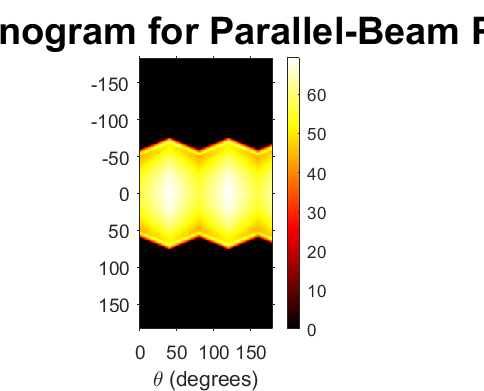

imshow(sinoRC, [], 'Xdata', 0:1:(aNum/2-1), 'Ydata', xpR, 'InitialMagnification', 'fit')     % composite sinogram
axis on
ax = gca;
colormap(gca, hot), colorbar
ax.TitleFontSizeMultiplier = 2;
title('Composite Sinogram for Parallel-Beam Projection')
xlabel('\theta (degrees)')

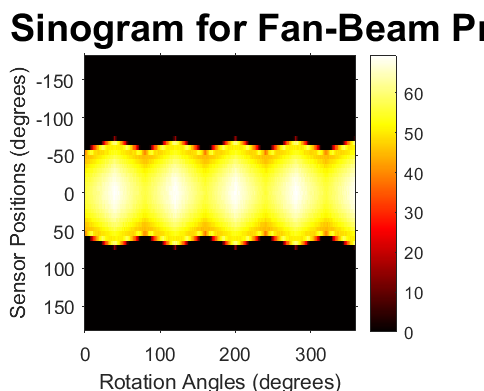


imshow(sinoFC, [], 'Xdata', rAF, 'Ydata', -180:1:180, 'InitialMagnification', 'fit')     % composite sinogram
axis on
ax = gca;
colormap(gca, hot), colorbar
ax.TitleFontSizeMultiplier = 2;
title('Composite Sinogram for Fan-Beam Projection')
xlabel('Rotation Angles (degrees)')
ylabel('Sensor Positions (degrees)')

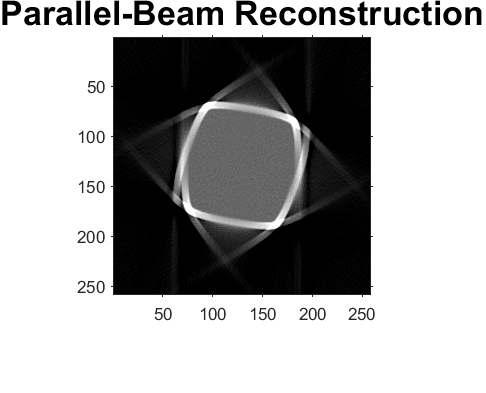


imshow(iradon(sinoRC, 0:1:(aNum/2-1)))    % reconstruct image
axis on
ax = gca;
ax.TitleFontSizeMultiplier = 2;
title('Parallel-Beam Reconstruction')

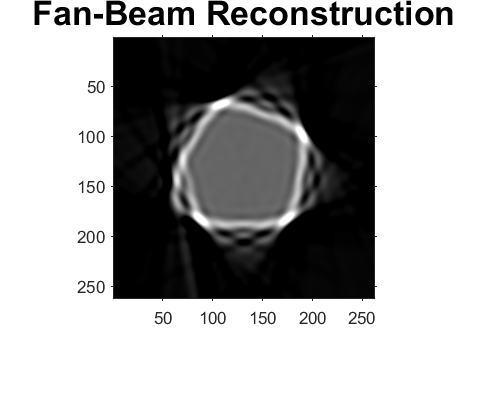

imshow(ifanbeam(sinoFC, vdF))    % reconstruct image
axis on
ax = gca;
ax.TitleFontSizeMultiplier = 2;
title('Fan-Beam Reconstruction')

## Expand only (Circle)

#### Variables

fCT = 50;             % [Hz] frequency CT, angles per second
fExp = 1/360;           % [Hz] rate of expansion/compression (human lungs 12~15 breaths/min)
expand = 36;            % [px] difference in radius btwn smallest/largest circles (human lungs double in volume?)

#### Creating Image

tCT = aNum/fCT;         % [s] total time of CT scan (# angles * angle freq)
tPxC = expand*fExp;        % [px/s] rate of change in radius
totalPx = 0:(tCT/aNum):tCT;    % total time (tCT) in increments of time corresponding to rate of change in angle

sCompC = zeros(imSize(1), imSize(2), aNum+1);     % array to store all images per angle (including starting image)
[imCol, imRow] = meshgrid(1:imSize(1), 1:imSize(2));    % to use in making circle/ellipse
filename = "ExpCircle.gif";       % exp/comp output gif

% Computing and recording image motion for duration of scan
for i=1:length(totalPx)     % increment at sampling times for each angle
    ovR = tPxC*totalPx(i);       % overall change in radius
    rCurr = radi + expand*(mod(ovR,expand));
    
    % Computing projection image at time of sampling
    outC = ((imCol - cenC(1)).^2 + (imRow - cenC(2)).^2) <= rCurr.^2;
    inC = ((imCol - cenC(1)).^2 + (imRow - cenC(2)).^2) <= (rCurr - imgOut).^2;
    sCompC(:, :, i) = outC - inC*(1-0.4);
    
    if i==1
        imwrite((sCompC(:, :, i)*255 +1), filename, "gif", "Loopcount", Inf, "DelayTime", (tCT/aNum));
    else
        imwrite((sCompC(:, :, i)*255 +1), filename, "gif", "WriteMode", "append", "DelayTime", (tCT/aNum));
    end
end
imshow(sCompC(:,:,1))        % image at starting time

#### Scanning

[sinoRC, xpR] = radon(sCompC(:,:,1));     % initializing sinogram at angle 0 deg
vdF = sqrt(imSize(1)^2 + imSize(2)^2) + 1;
[sinoFC, sPF, rAF] = fanbeam(sCompC(:,:,1), vdF);     % initializing sinogram at angle 0 deg

for theta = 2:1:aNum        % increment through angles 1-359 deg
    if (theta <= aNum/2)
       scanRC = radon(sCompC(:,:, theta));
       sinoRC(:, theta) = scanRC(:, theta);  % replacing "slices" of sinogram with image at time corresponding to angle 
    end
    scanFC = fanbeam(sCompC(:,:, theta), vdF);
    sinoFC(:, theta) = scanFC(:, theta);  % replacing "slices" of sinogram with image at time corresponding to angle
end

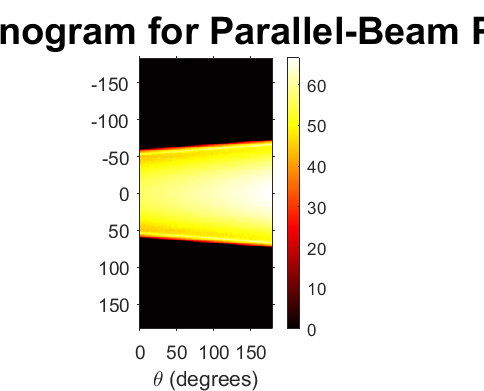

imshow(sinoRC, [], 'Xdata', 0:1:(aNum/2-1), 'Ydata', xpR, 'InitialMagnification', 'fit')     % composite sinogram
axis on
ax = gca;
colormap(gca, hot), colorbar
ax.TitleFontSizeMultiplier = 2;
title('Composite Sinogram for Parallel-Beam Projection')
xlabel('\theta (degrees)')

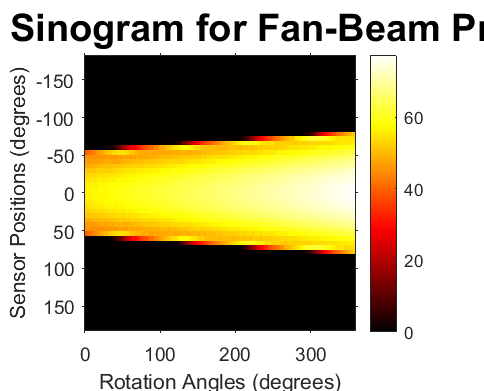


imshow(sinoFC, [], 'Xdata', rAF, 'Ydata', -180:1:180, 'InitialMagnification', 'fit')     % composite sinogram
axis on
ax = gca;
colormap(gca, hot), colorbar
ax.TitleFontSizeMultiplier = 2;
title('Composite Sinogram for Fan-Beam Projection')
xlabel('Rotation Angles (degrees)')
ylabel('Sensor Positions (degrees)')

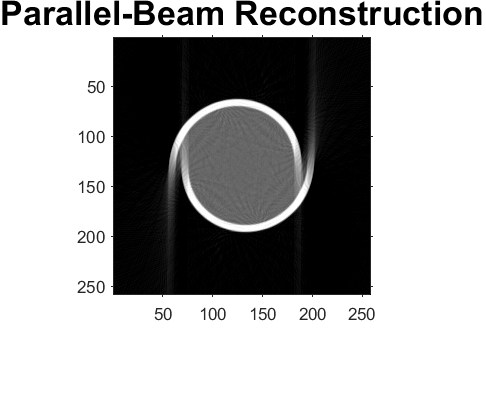


imshow(iradon(sinoRC, 0:1:(aNum/2-1)))    % reconstruct image
axis on
ax = gca;
ax.TitleFontSizeMultiplier = 2;
title('Parallel-Beam Reconstruction')

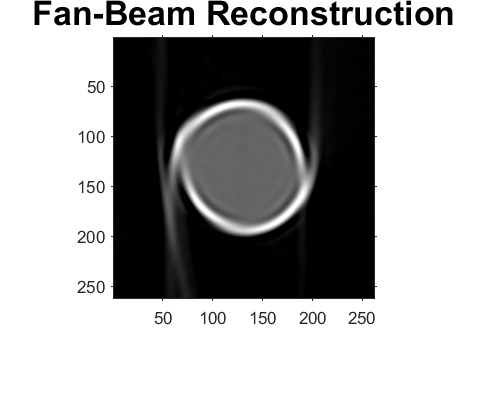

imshow(ifanbeam(sinoFC, vdF))    % reconstruct image
axis on
ax = gca;
ax.TitleFontSizeMultiplier = 2;
title('Fan-Beam Reconstruction')

## Compress only (Circle)

#### Variables

comp = 36;            % [px] difference in radius btwn smallest/largest circles (human lungs double in volume?)

#### Creating Image

sCompC = zeros(imSize(1), imSize(2), aNum+1);     % array to store all images per angle (including starting image)
[imCol, imRow] = meshgrid(1:imSize(1), 1:imSize(2));    % to use in making circle/ellipse
filename = "CompCircle.gif";       % exp/comp output gif

% Computing and recording image motion for duration of scan
for i=1:length(totalPx)     % increment at sampling times for each angle
    ovR = tPxC*totalPx(i);       % overall change in radius
    
    % find expansion/compression at time of sampling
    rCurr = radi - comp*(mod(ovR,expand));
    
    % Computing projection image at time of sampling
    outC = ((imCol - cenC(1)).^2 + (imRow - cenC(2)).^2) <= rCurr.^2;
    inC = ((imCol - cenC(1)).^2 + (imRow - cenC(2)).^2) <= (rCurr - imgOut).^2;
    sCompC(:, :, i) = outC - inC*(1-0.4);
    
    if i==1
        imwrite((sCompC(:, :, i)*255 +1), filename, "gif", "Loopcount", Inf, "DelayTime", (tCT/aNum));
    else
        imwrite((sCompC(:, :, i)*255 +1), filename, "gif", "WriteMode", "append", "DelayTime", (tCT/aNum));
    end
end
imshow(sCompC(:,:,1))        % image at starting time

#### Scanning

% sinoC = scan(sCompC(:,:,1));     % initializing sinogram at angle 0 deg
[sinoRC, xpR] = radon(sCompC(:,:,1));     % initializing sinogram at angle 0 deg
vdF = sqrt(imSize(1)^2 + imSize(2)^2) + 1;
[sinoFC, sPF, rAF] = fanbeam(sCompC(:,:,1), vdF);     % initializing sinogram at angle 0 deg

for theta = 2:1:aNum        % increment through angles 1-359 deg
    if (theta <= aNum/2)
       scanRC = radon(sCompC(:,:, theta));
       sinoRC(:, theta) = scanRC(:, theta);  % replacing "slices" of sinogram with image at time corresponding to angle 
    end
    scanFC = fanbeam(sCompC(:,:, theta), vdF);
    sinoFC(:, theta) = scanFC(:, theta);  % replacing "slices" of sinogram with image at time corresponding to angle
end

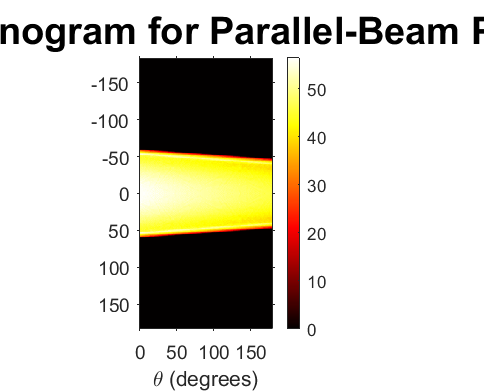

imshow(sinoRC, [], 'Xdata', 0:1:(aNum/2-1), 'Ydata', xpR, 'InitialMagnification', 'fit')     % composite sinogram
axis on
ax = gca;
colormap(gca, hot), colorbar
ax.TitleFontSizeMultiplier = 2;
title('Composite Sinogram for Parallel-Beam Projection')
xlabel('\theta (degrees)')

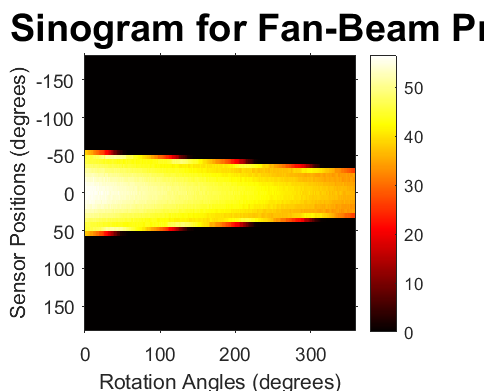


imshow(sinoFC, [], 'Xdata', rAF, 'Ydata', -180:1:180, 'InitialMagnification', 'fit')     % composite sinogram
axis on
ax = gca;
colormap(gca, hot), colorbar
ax.TitleFontSizeMultiplier = 2;
title('Composite Sinogram for Fan-Beam Projection')
xlabel('Rotation Angles (degrees)')
ylabel('Sensor Positions (degrees)')

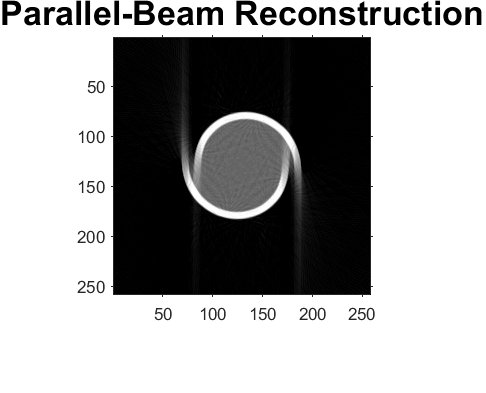


imshow(iradon(sinoRC, 0:1:(aNum/2-1)))    % reconstruct image
axis on
ax = gca;
ax.TitleFontSizeMultiplier = 2;
title('Parallel-Beam Reconstruction')

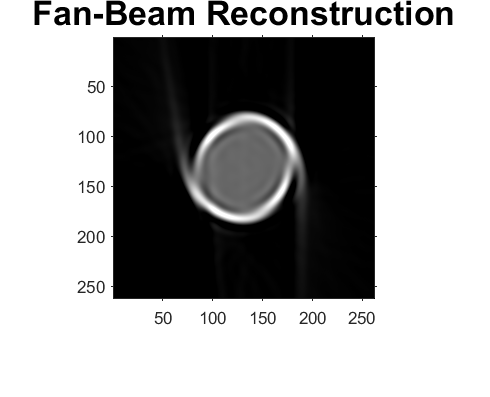

imshow(ifanbeam(sinoFC, vdF))    % reconstruct image
axis on
ax = gca;
ax.TitleFontSizeMultiplier = 2;
title('Fan-Beam Reconstruction')